Setup

f = [110,220,330,440,550];
anSignal = [1.5,-2.8,3.7,1.1,0.4];
bnSignal = [-0.4,-3.9,0,-0.8,0];

freq = 0:10:600;
an = zeros(size(freq));
bn = zeros(size(freq));

an(f/10+1) = anSignal;
bn(f/10+1) = bnSignal;

% Second definition
An = sqrt(an.^2 + bn.^2);
phin = atan2(bn,an);

% First definition reconstruction
t = linspace(0,2/110,500);
ft = zeros(size(t));
L = 0.5;
n = freq;
for k = 1:numel(n)
    ft = ft + an(k)*cos((n(k)*pi/L).*t) ...
            + bn(k)*sin((n(k)*pi/L).*t);
end

% Second definition reconstruction
ft2 = zeros(size(t));
L = 0.5;
n = freq;
for k = 1:numel(n)
    ft2 = ft2 + An(k)*cos((n(k)*pi/L).*t - phin(k));
end

colors=lines(10);

Time domain plot

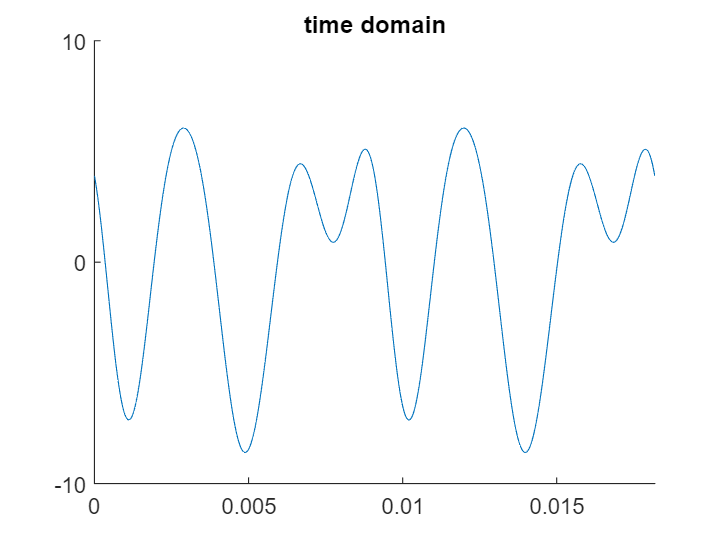

% Time domain
figure
plot(t,ft)
title("time domain")
axis tight
box off
ylim([-10,10])
xticks([0,0.005,0.01,0.015])
yticks([-10,0,10])

First definition coefficients

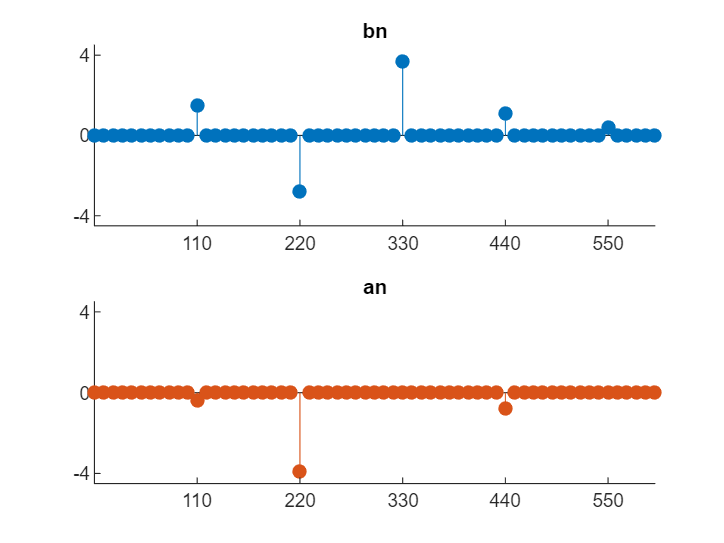

% an bn plots
figure

subplot(2,1,1)
stem(freq,an,"filled",'color',colors(1,:))
ylim([-4.5,4.5])
yticks([-4,0,4])
box off
xticks([110,220,330,440,550])
title('bn')

subplot(2,1,2)
stem(freq,bn,"filled",'color',colors(2,:))
ylim([-4.5,4.5])
yticks([-4,0,4])
title('an')
box off
xticks([110,220,330,440,550])

Second definition

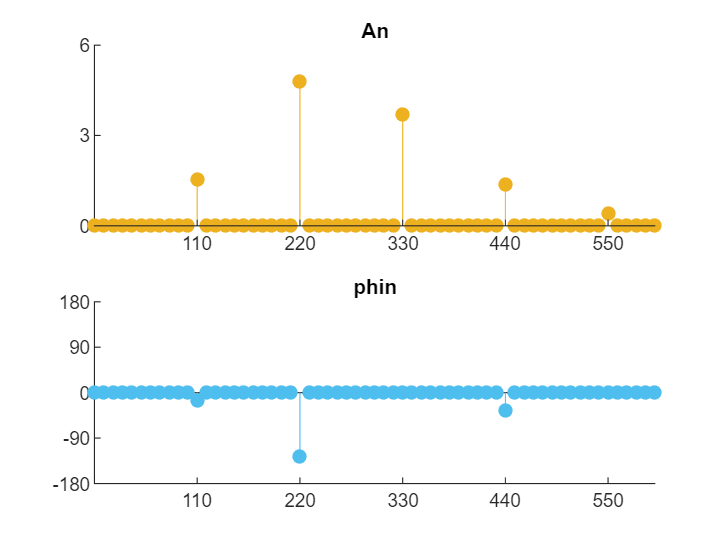

figure

subplot(2,1,1)
stem(freq,An,"filled",'color',colors(3,:))
xticks([110,220,330,440,550])
yticks([0,3,6])
ylim([0,6])
box off
title('An')

subplot(2,1,2)
stem(freq,phin*180/(pi),"filled",'color',colors(6,:))
ylim([-180,180])
yticks([-180,-90,0,90,180])
title('phin')
xticks([110,220,330,440,550])
box off

Second definition plot

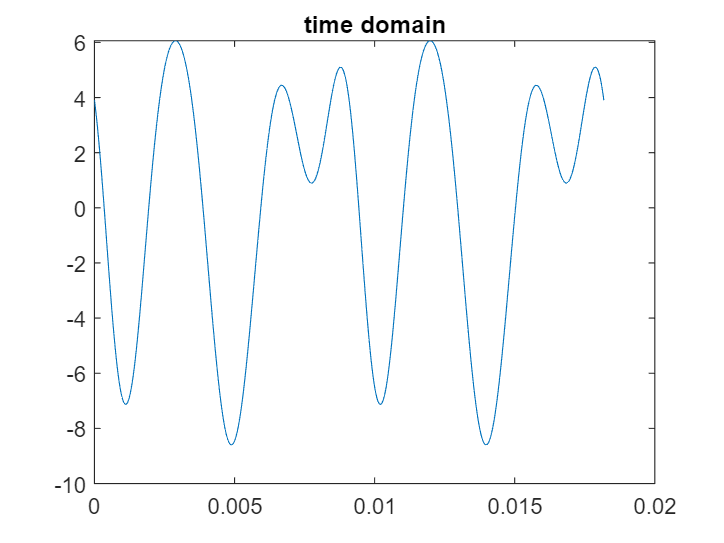

figure
plot(t,ft2)
title("time domain")